clear;clc;close all;fclose('all');

Parameters:

ZC_root = 13;
nfft = 4096;
Nzc = nfft/2;
Nzc2 = 2053; % Closes prime number less than 2048

ZC Sequence:

sync_tx = exp(-1i*pi*ZC_root*(1:Nzc).*((1:Nzc)+1)/Nzc);
sync_tx_zp = [zeros(1,(nfft-Nzc)/2),sync_tx,zeros(1,(nfft-Nzc)/2)]; % Padd zeros for 4096 IFFT
sync_tx_time = ifft(ifftshift(sync_tx_zp),nfft);
sync_coef = conj(fliplr(sync_tx_time));
sync_corr = abs(filter(sync_coef,1,sync_tx_time));
max(sync_corr)

ans =    0.500000000000000


2039 ZC Sequence:

sync_tx2 = exp(-1i*pi*ZC_root*(1:Nzc2).*((1:Nzc2)+1)/Nzc2);
sync_tx2 = sync_tx2(1:2048);
Nzc2 = 2048;
sync_tx_zp2 = [zeros(1,1024+2048-Nzc2),sync_tx,zeros(1,1024)]; % Pad zeros for 4096 IFFT
sync_tx_time2 = ifft(ifftshift(sync_tx_zp2),nfft);
sync_coef2 = conj(fliplr(sync_tx_time2));
sync_corr2 = abs(filter(sync_coef2,1,sync_tx_time2));
max(sync_corr2)

ans =    0.500000000000000


Plot:

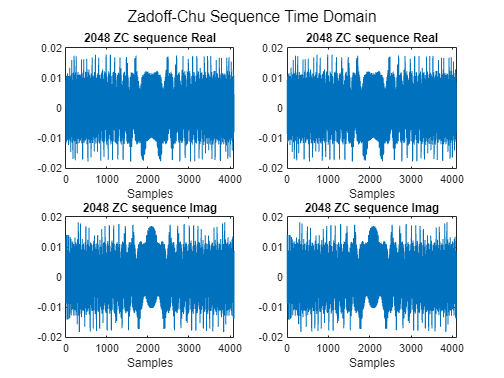

figure(),subplot(2,2,1),plot(real(sync_tx_time)),xlabel('Samples'),title([num2str(Nzc),' ZC sequence Real'])
subplot(2,2,3),plot(imag(sync_tx_time)),xlabel('Samples'),title([num2str(Nzc),' ZC sequence Imag'])
subplot(2,2,2),plot(real(sync_tx_time2)),xlabel('Samples'),title([num2str(Nzc2),' ZC sequence Real'])
subplot(2,2,4),plot(imag(sync_tx_time2)),xlabel('Samples'),title([num2str(Nzc2),' ZC sequence Imag']),sgtitle('Zadoff-Chu Sequence Time Domain')

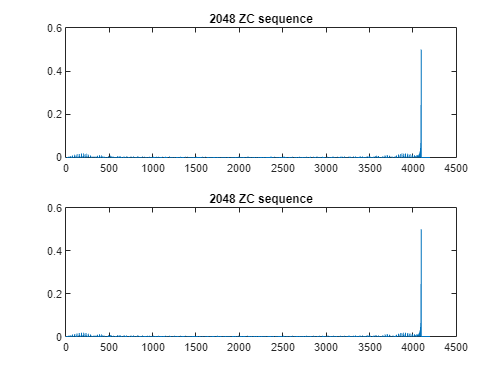

figure(),subplot(2,1,1),plot([real(sync_corr),zeros(1,100)]),title([num2str(Nzc),' ZC sequence'])
subplot(2,1,2),plot([real(sync_corr2),zeros(1,100)]),title([num2str(Nzc2),' ZC sequence'])

Coefficients:

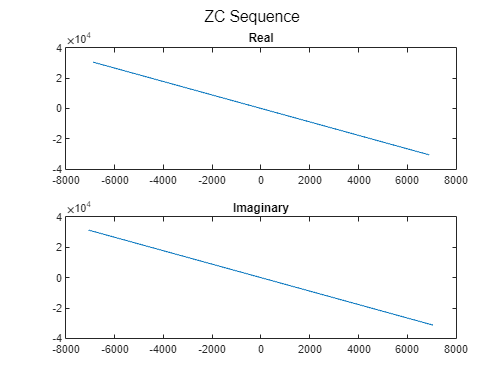

sync_coef = conj(fliplr(sync_tx_time));
sync_coef_i = real(sync_coef); sync_coef_q = imag(sync_coef);
max_val = max(sync_coef);
scaled_sync_coef_i = int16(sync_coef_i ./ max_val .* 32767);
scaled_sync_coef_q = int16(sync_coef_q ./ max_val .* 32767);
figure(),subplot(2,1,1),plot(scaled_sync_coef_i),title('Real')
subplot(2,1,2),plot(scaled_sync_coef_q),title('Imaginary'),sgtitle('ZC Sequence')

Write to coe files for Xilinx FIR compiler:

% file = fopen('../Xilinx/Vivado/modules/data/zc_4096_nfft_2048_ZC_13_root_i.coe','w');
% fprintf(file,"radix=10;\n");
% fprintf(file,"coefdata=");
% fprintf(file,"%d,",scaled_sync_coef_i(1:end-1));
% fprintf(file,"%d;",scaled_sync_coef_i(end));
% fclose('all');
% 
% file = fopen('../Xilinx/Vivado/modules/data/zc_4096_nfft_2048_ZC_13_root_q.coe','w');
% fprintf(file,"radix=10;\n");
% fprintf(file,"coefdata=");
% fprintf(file,"%d,",scaled_sync_coef_q(1:end-1));
% fprintf(file,"%d;",scaled_sync_coef_q(end));
% fclose('all');